# AMECH HW11


$$\begin{array}{l}
\vec{F_{\mathrm{cor}} } =-2m\vec{\omega} \times \vec{v} \\
\vec{a_{\mathrm{cor}} } =-2\vec{\omega} \times \vec{v} 
\end{array}$$



$$\begin{array}{l}
\vec{\omega} =\omega \left(\sin \theta \hat{y} +\cos \theta \hat{z} \right)\\
\vec{v} =v_x \hat{x} +v_y \hat{y} ,v_x =0\;\textrm{for}\;\textrm{due}\;\textrm{north},v_y =0\;\textrm{for}\;\textrm{due}\;\textrm{east}
\end{array}$$



$$\vec{a_{\textrm{cor}} } =-2\vec{\omega} \times \vec{v} =-2\omega \left\lbrack \left(v_z \sin \theta -v_y \cos \theta \right)\hat{x} -\left(-v_x \cos \theta \right)\hat{y} +\left(-v_x \sin \theta \right)\hat{z} \right\rbrack$$



$$\vec{a_{\textrm{cor}} } =-2\omega \left(\left(v_z \sin \theta -v_y \cos \theta \right)\hat{x} +v_x \cos \theta \hat{y} -v_x \sin \theta \hat{z} \right)$$



$$\begin{array}{l}
F_g =-{\textrm{mg}}_{\textrm{eff}} \hat{z} \\
a_g =-g_{\textrm{eff}} \hat{z} 
\end{array}$$



$$\overset{\ldotp \ldotp }{x} =-2\omega \left(v_z \sin \theta -v_y \cos \theta \right)$$



$$\begin{array}{l}
\overset{\ldotp \ldotp }{y} =-2\omega v_x \cos \theta \\
\overset{\ldotp \ldotp }{z} =-g_{\mathrm{eff}} +2\omega v_x \sin \theta 
\end{array}$$



$$g_{\mathrm{eff}} =g-\omega^2 {\mathrm{Rcos}}^2 \theta$$


% Shooting EAST
% Init vars
vi = 700 ;
tspan = 0:0.0001:1.42899 ; % tspan found by vi/d where vi is initial velocity and d is distance to target
% ODE functions from above
function xdot = myode(t, x)
% Initial conditions
    theta = deg2rad(44.9778) ; % latitude of MN (rads)
    omega = 7.2921*10^(-5) ; % rotational speed of the earth
    g = 9.8 -(omega^2*(6378137)*cos(theta)^2) ; % effective graviational acceleration
    % extract variables
    z = x(5:6) ;
    y = x(3:4) ;
    x = x(1:2) ;
    % setup diff eqs
    xdot(1) = x(2) ;
    xdot(2) = -2*omega*(z(2)*sin(theta) - y(2)*cos(theta)) ;
    ydot(1) = y(2) ;
    ydot(2) = -2*omega*x(2)*cos(theta) ;
    zdot(1) = z(2) ;
    zdot(2) = -g+2*omega*x(2)*sin(theta) ;
    % combine for output to be used in ode45
    xdot = [xdot(1), xdot(2), ydot(1), ydot(2), zdot(1), zdot(2)]' ;
end
% same ode but in singapore
function xdot = myodeSingapore(t, x)
% Initial conditions
    theta = deg2rad(1.3521) ; % latitude of MN (rads)
    omega = 7.2921*10^(-5) ; % rotational speed of the earth
    g = 9.8 -(omega^2*(6378137)*cos(theta)^2) ; % effective graviational acceleration
    % extract variables
    z = x(5:6) ;
    y = x(3:4) ;
    x = x(1:2) ;
    % setup diff eqs
    xdot(1) = x(2) ;
    xdot(2) = -2*omega*(z(2)*sin(theta) - y(2)*cos(theta)) ;
    ydot(1) = y(2) ;
    ydot(2) = -2*omega*x(2)*cos(theta) ;
    zdot(1) = z(2) ;
    zdot(2) = -g+2*omega*x(2)*sin(theta) ;
    % combine for output to be used in ode45
    xdot = [xdot(1), xdot(2), ydot(1), ydot(2), zdot(1), zdot(2)]' ;
end
% ODE functions without gravity
function xdot = myodenog(t, x)
% Initial conditions
    theta = deg2rad(90 - 44.9778) ; % pi/2 - latitude of MN (rads)
    omega = 7.2921*10^(-5) ; % rotational speed of the earth
    % extract variables
    z = x(5:6) ;
    y = x(3:4) ;
    x = x(1:2) ;
    % setup diff eqs
    xdot(1) = x(2) ;
    xdot(2) = -2*omega*(z(2)*sin(theta) - y(2)*cos(theta)) ;
    ydot(1) = y(2) ;
    ydot(2) = -2*omega*x(2)*cos(theta) ;
    zdot(1) = z(2) ;
    zdot(2) = 2*omega*x(2)*sin(theta) ;
    % combine for output to be used in ode45
    xdot = [xdot(1), xdot(2), ydot(1), ydot(2), zdot(1), zdot(2)]' ;
end
% same ode but in singapore
function xdot = myodeSingaporenog(t, x)
% Initial conditions
    theta = deg2rad(90 - 1.3521) ; % pi/2 -latitude of MN (rads)
    omega = 7.2921*10^(-5) ; % rotational speed of the earth
    % extract variables
    z = x(5:6) ;
    y = x(3:4) ;
    x = x(1:2) ;
    % setup diff eqs
    xdot(1) = x(2) ;
    xdot(2) = -2*omega*(z(2)*sin(theta) - y(2)*cos(theta)) ;
    ydot(1) = y(2) ;
    ydot(2) = -2*omega*x(2)*cos(theta) ;
    zdot(1) = z(2) ;
    zdot(2) = 2*omega*x(2)*sin(theta) ;
    % combine for output to be used in ode45
    xdot = [xdot(1), xdot(2), ydot(1), ydot(2), zdot(1), zdot(2)]' ;
end
% Solve ode with initial conditions of shooting east in MN
xi = [0, vi, 0, 0, 0, 0] ;
[MNEt, MNEx] = ode45(@myode, tspan, xi) ;
[MNEtnog, MNExnog] = ode45(@myodenog, tspan, xi) ;
% Solve ode with initial conditions of shooting north in MN
xi = [0, 0, 0,vi, 0, 0] ;
[MNNt, MNNx] = ode45(@myode, tspan, xi) ;
[MNNtnog, MNNxnog] = ode45(@myodenog, tspan, xi) ;
% Solve ode with initial conditions of shooting east in Singapore
xi = [0, vi, 0, 0, 0, 0] ;
[SGEt, SGEx] = ode45(@myodeSingapore, tspan, xi) ;
[SGEtnog, SGExnog] = ode45(@myodeSingaporenog, tspan, xi) ;
% Solve ode with initial conditions of shooting north in Singapore
xi = [0, 0, 0, vi, 0, 0] ;
[SGNt, SGNx] = ode45(@myodeSingapore, tspan, xi) ;
[SGNtnog, SGNxnog] = ode45(@myodeSingaporenog, tspan, xi) ;
disp(['Drift when shooting EAST in MN: y = ', num2str(MNEx(end, 3)), '(m) | z = ', num2str(MNEx(end, 5)), '(m)'])

Drift when shooting EAST in MN: y = -0.073724(m) | z = -9.9136(m)


disp(['Drift with no g shooting EAST in MN: y = ', num2str(MNExnog(end, 3)), '(m) | z = ', num2str(MNExnog(end, 5))])

Drift with no g shooting EAST in MN: y = -0.073667(m) | z = 0.073724


disp(['Drift when shooting NORTH in MN: x = ', num2str(MNNx(end, 1)), '(m) | z = ', num2str(MNNx(end, 5)), '(m)'])

Drift when shooting NORTH in MN: x = 0.074214(m) | z = -9.9873(m)


disp(['Drift with no g shooting NORTH in MN: x = ', num2str(MNNxnog(end, 1)), '(m) | z = ', num2str(MNNxnog(end, 5))])

Drift with no g shooting NORTH in MN: x = 0.073667(m) | z = 3.6198e-06


disp(['Drift when shooting EAST in Singapore: y = ', num2str(SGEx(end, 3)), '(m) | z = ', num2str(SGEx(end, 5)), '(m)'])

Drift when shooting EAST in Singapore: y = -0.10419(m) | z = -9.9675(m)


disp(['Drift with no g shooting EAST in Singapore: y = ', num2str(SGExnog(end, 3)), '(m) | z = ', num2str(SGExnog(end, 5))])

Drift with no g shooting EAST in Singapore: y = -0.0024592(m) | z = 0.10419


disp(['Drift when shooting NORTH in Singapore: x = ', num2str(SGNx(end, 1)), '(m) | z = ', num2str(SGNx(end, 5)), '(m)'])

Drift when shooting NORTH in Singapore: x = 0.10421(m) | z = -9.97(m)


disp(['Drift with no g shooting NORTH in Singapore: x = ', num2str(SGNxnog(end, 1)), '(m) | z = ', num2str(SGNxnog(end, 5))])

Drift with no g shooting NORTH in Singapore: x = 0.0024592(m) | z = 1.7078e-07


Comparing these tables to the ones calculated on the pen and paper part of the homework, one thing sticks out. In the homework I calculated no drift in the z direcitons when shooting north, here we see a slight drift although very small. This could be an artifact of ode45 or an artifact of the assumptions made when calculating the first table. Everything else lines up.

SGEx(:, 1) % print to check where arrow hits target at 1000m(idx: 14287)

ans = 1.0e+03 *

         0
    0.0001
    0.0001
    0.0002
    0.0003
    0.0004
    0.0004
    0.0005
    0.0006
    0.0006


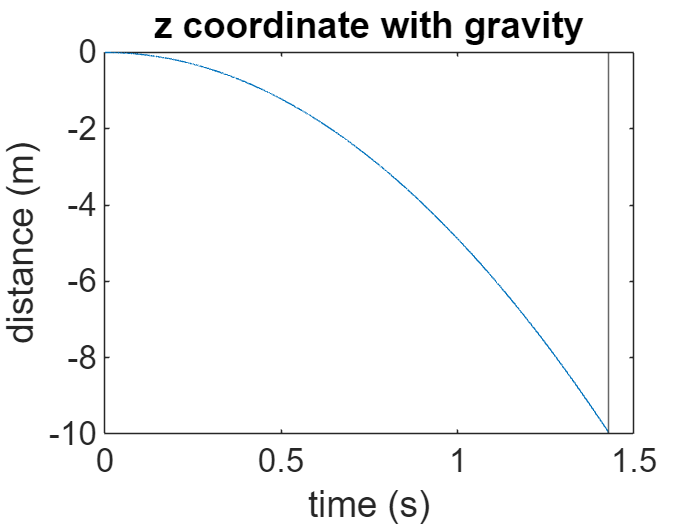


% Plot figures showing the flight times in Singapore shooting EAST
clf
figure
plot(SGEt, SGEx(:, 5))
set(gca, 'fontsize', 20)
ylabel('distance (m)')
xlabel('time (s)')
title('z coordinate with gravity')
xline(SGEt(14287))

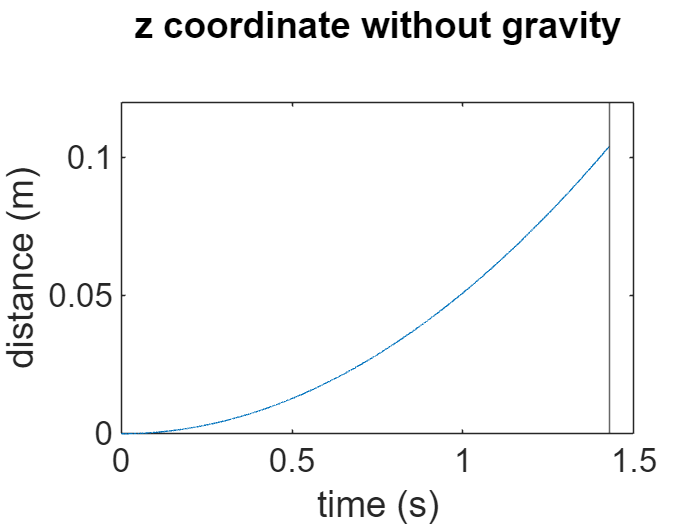

clf
figure
plot(SGEtnog, SGExnog(:, 5))
set(gca, 'fontsize', 20)
ylabel('distance (m)')
xlabel('time (s)')
title('z coordinate without gravity')
subtitle(' ')
xline(SGEtnog(14287))

They would not hit the bullseye as it would drift 10cm due to earth's rotation while the bullseye is only 2cm in diameter.